# 人力资源分配问题

## **问题描述**

某项目包含 n 个子任务，记完成第 i 个子任务所需投入的工时为 $D_{i}$（人*天），任意时刻投入第i个子任务的人数都不得超过 $M_{i}$人，共有劳动力X人。$X, T \in R$. 

1. 如何分配可使完成所有任务的总时间T（天）最短，T是多少？ 

2. 如果一些子任务不能在项目开始时立即开工，而是需要一定的预热时间才能开始投入人力，记第i个任务的预热时间为$R_{i}$，如何解决问题1？

3. 假如子任务不是相互独立的，一些子任务依赖于另一些子任务先完成才能开工，依赖关系用邻接矩阵表示的有向图G描述，应如何投入人力，找到最短施工时间？比如D=[1*10^3,1,1],M=[100 100 0.02], X=2, 记第1,2,3个任务的node为A,B,C

## **Solution for question 1**

## **思路一**

尽量使每人每天都有活儿干即可。记t时刻分配到第i个任务的劳动力为$S_{i}(t)$，约束条件：$\sum_{i=1}^{n}S_{i}(t)\leq X$ 且 $0\leq S_{i}(t)\leq M_{i}$。令$\int_{0}^{T_{i}}S_{i}(t)dt=D_{i}$，则 $T=max(T_{i})$ (i=1,...,n)

目标： min T

因为$X\in R$，在无M约束条件下，以所有子任务同时完工为目标，可使T最小，最小值为$T=\sum_{i=1}^{n}D_{i}/X$,显然$S_{i}\equiv \frac{D_{i}}{\sum_{i=1}^{n} D{i}}X$；在M约束条件下，若$\frac{D_{i}}{\sum_{i=1}^{n} D{i}}X>M_{i}$，取$S_{i}=M_{i}$，最终完工时间为$T=max(\frac{D_{i}}{S_{i}})$.

clear;% This algorithm has O(n) running time
X=randi(30); D=ceil(abs(randn(1,25)*5+5)); M=randi([1,6],1,25);
S=D/sum(D)*X;%若不超过M
S(S>M)=M(S>M); %若超过M
T=max(D./S)

T = 11

%用规划求解器验证结果
d=size(D);
[~,~,T2]=fminimax(@(x) D./x,ones(d),ones(d),X,[],[],zeros(d),M)


Local minimum possible. Constraints satisfied.

fminimax stopped because the size of the current search direction is less than
twice the default value of the step size tolerance and constraints are 
satisfied to within the default value of the constraint tolerance.

<stopping criteria details>



T2 = 11.0000

## **Solution for question 1 **

## **思路二 **A greedy method

example: D=[6,1], M=[3,1], X=3

记t时刻分配到第i个任务的劳动力为$S_{i}(t)$，$\sum_{i=1}^{n}S_{i}(t)\leq X$且$0\leq S_{i}(t)\leq M_{i}$，对子任务i=1,...,n， 按升序排列 ${M_{i}}$ 及其相应的子任务i，记排列后的任务为i=1,...,n。排列后，从i=1到i=n依次分配劳力，每次都尽可能多的分配劳力给每个子任务。某子任务完成后，空闲出的劳力继续分配给后续任务。

At time t=0, find the first k s.t $X\leq \sum_{i=1}^{k}M_{i}$, the first k sequences would then run first. for i=1,...,k-1 $S_{i}=M_{i}$, $S_{k}=X-\sum_{i=1}^{k-1}S_{i}$, at time $t=t+min(\frac{D_{1}}^{S_{1}},...,\frac{D_{k}}^{S_{k}})$，update as follow:

1. find task j which has $min(\frac{D_{1}}^{S_{1}},...,\frac{D_{k}}^{S_{k}})$, 

2. transfer out $S_{j}$ workers into $ S_{k}$ first, $S_{k+1}$ second and so on, till the first p (p>=0) s.t. $S_{k+p}=X-\sum_{i=1}^{k+p-1}M_{i}$, 

3. set k=k+p then 

Repeat until all tasks are done

## **Solution for question 2**

## **思路一**

记第i个任务的预热时间为$R_{i}$，记t时刻分配到第i个任务的劳动力为$S_{i}(t)$，约束条件：$\sum_{i=1}^{n}S_{i}(t)\leq X$ 且 $0\leq S_{i}(t)\leq M_{i}*I(t\geq R_{i})$。令$\int_{0}^{T_{i}}S_{i}(t)dt=D_{i}$，则 $T=max(T_{i})$ (i=1,...,n)

目标： min T

以上模型可进一步写为如下形式.

**Notations**

- [u,~,index]=unique([R,0]), u表示向量[R,0]中的无重复元素的升序排列, index(i)表示[R,0]中的第i个元素在u中的位置索引

- 记$dt=diff(u)=[dt_{1},...,dt_{r}]$，则dt为连续时间段t离散化为r段后的表达，例如R=[1,3,3,6]时，u=[0,1,3,6],dt=[1,2,3]

- 记$S_{n\times (r+1)}=\pmatrix{
 S_{1,1}&  \cdots & S_{1,r} & S_{1,r+1}\cr 
 \vdots &  \ddots &  \vdots & \vdots \cr 
 S_{n,1}&  \cdots &  S_{n,r}& S_{n,r+1}
}$ ,$S_{i,j}$对应于第i个子任务在第j时间段内的人力分配. 

**Constraints**

- $\sum_{i=1}^{n}S_{i,j}\leq X$  and $0\leq S_{i,j}\leq M_{i}$ for $\forall j=1,...,r+1$.  

- $S_{i,j}=0$ for $\forall j<index(i), i=1,...,n$

- 
$$S_{n\times (r+1)}\cdot \pmatrix{dt\cr \Delta t}=\pmatrix{
 S_{1,1}&  \cdots & S_{1,r} & S_{1,r+1}\cr 
 \vdots &  \ddots &  \vdots & \vdots \cr 
 S_{n,1}&  \cdots &  S_{n,r}& S_{n,r+1}
}\cdot \pmatrix{dt_{1}\cr\vdots\cr dt_{r}\cr\Delta t}=D^{T}$$


**Goal: **minimize $sum([dt, \Delta t])$ over $(S,\Delta t)$ $\iff$ minimize $\Delta t$, where$\Delta t=max \{(D^{T}-S(:,1:end-1)\cdot dt^{T})./S(:,end)\}$

the final total time required to finish all the task is then T=$sum([dt, \Delta t])$

% The above algorithm is implemented as a function that is called MinTAllocation
clear;%data initialization
X=randi(30), D=ceil(abs(randn(1,10)*20+15)), M=randi([1,6],1,10), R=randi([0,3],1,10)

X = 8

D =      6    42     7    13    33     9    36     9    36    28


M =      3     1     2     3     2     2     5     3     6     3


R =      3     1     3     3     1     0     3     3     1     2


%D = [160 20 10];M = [20 2 20];R = [0 0 2];X = 14;
[S1,T1]=MinTAllocation(X,D,M,R)


Local minimum possible. Constraints satisfied.

fminimax stopped because the size of the current search direction is less than
twice the default value of the step size tolerance and constraints are 
satisfied to within the default value of the constraint tolerance.

<stopping criteria details>



S1 =          0         0         0    0.7458
         0    1.0000    1.0000    1.0000
         0         0         0    0.7458
         0         0         0    0.7458
         0    1.0007    1.0007    0.7751
    1.0000    1.0000    1.0000    0.7458
         0         0         0    0.9002
         0         0         0    0.7458
         0    1.0029    1.0029    0.8499
         0         0    1.0000    0.7458


T1 = 43.0000

%t=timeit(@()MinTAllocation(X,D,M,R))

## **Solution for question 2**

## **思路二**

- 同思路一，仍然把时间分成r段，例如R=[1,3,3,6,0]时，[u,~,index]=unique([R,0]), 返回u=[0,1,3,6], 因此我们把时间分成了r=4段：[0,1], [1,3], [3,6], [6,$\infty $]. dt=diff(u)返回前r-1段时间的时长：dt=[1,2,3].

- 在第j (j的初始值为1) 段时间区间内，以$D_{i}$为权重，将劳力X按加权比分配到该时间段内已经可以开工的子任务中，若按该法分配的劳力超出某子任务的劳力上限，则将超出部分以按D加权的方式分配到其它劳力未满的子任务中，重复此过程，直到所有劳力X都投入使用，或所有可开工的子任务都达到劳力的上限。记此时第i个子任务分配到的劳力为$S_{i}$人。计算第j阶段过后各个子任务的剩余工作量$D=(D-S\cdot dt_j)\cdot I(D-S\cdot dt_{j}>=0)$. 更新j=j+1

- 重复步骤2-3直到j=r+1, 此时所有子任务都已经过预热期，按Solution 1 for question 1 思路一 中的办法计算第r+1阶段完成所有剩余任务所需的最短时间$\Delta t$，则总时间为$max(R)+\Delta t$

% The above algorithm is implemented as a function that is called MinTAllocation2
X=10;D=[500 5 20 20 100];M=[10 6 2 10 5]; R=[0 0 10 11 0];
t=timeit(@()MinTAllocation2(X,D,M,R));
[S2,T2]=MinTAllocation2(X,D,M,R),disp(['Running Time:',num2str(t),'s'])

S2 =     8.2645    7.9496    7.6524
    0.0826    0.0795    0.0765
         0    0.3810    0.3667
         0         0    0.3738
    1.6529    1.5899    1.5305


T2 = 64.5000

Running Time:0.00010396s


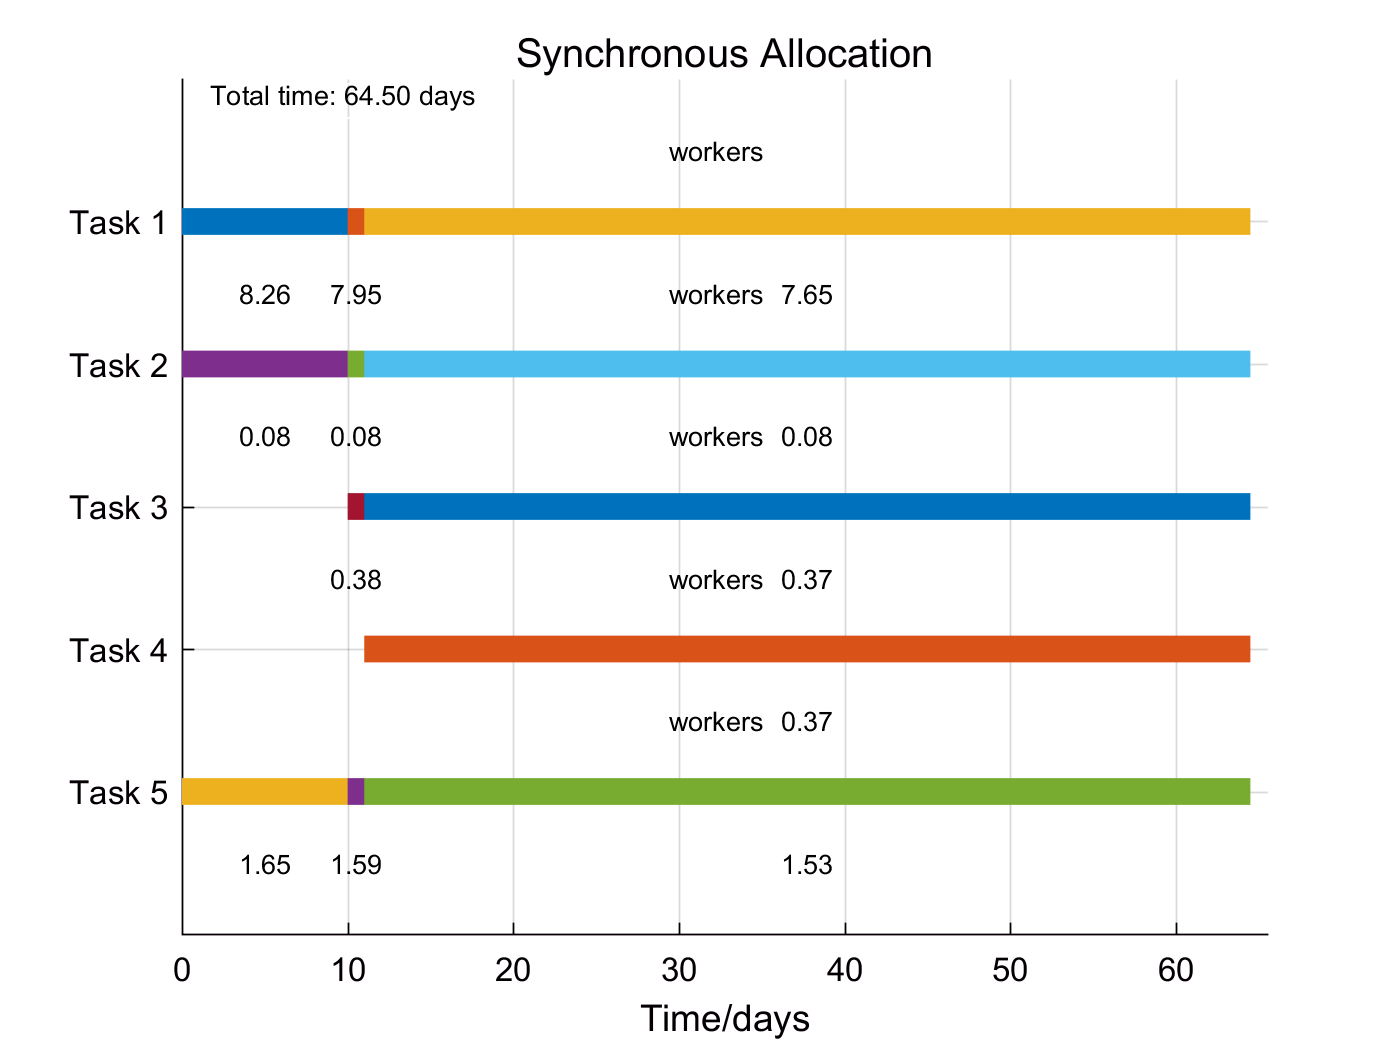

VisualPlan(X,D,M,R)

## **Solutions for Question 2  **

## **思路三 A greedy method**

Carry out the process in Solution for question 1 思路二 for every phase of ready. 